# **Comparaison des profils EMG avec SPM1D**

% Script pour exécuter l'analyse des EMG avec SPM1D
cd 'C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Scripts\2) Electromyography\Functional\Plot_functional_spm1d'
fprintf('Analyse des profils EMG moyens par muscle avec SPM1D\n');

Analyse des profils EMG moyens par muscle avec SPM1D


fprintf('======================================================\n\n');


% Ajouter le chemin vers la bibliothèque SPM1D
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Statistics\spm1dmatlab-master'))

% Demander le nombre de fichiers à analyser
fprintf('\nCombien de fichiers souhaitez-vous analyser? (1-3): ');


Combien de fichiers souhaitez-vous analyser? (1-3): 

num_files = str2double(input('', 's'));

% Vérifier la validité du nombre
if isnan(num_files) || num_files < 1 || num_files > 3
    fprintf('Nombre invalide. Utilisation d''un seul fichier par défaut.\n');
    num_files = 1;
end

% Collecter les noms de fichiers
data_files = cell(num_files, 1);
for i = 1:num_files
    default_file = sprintf('combined_functional_data_for_spm1d_%d.mat', i);
    if i == 1
        default_file = 'combined_functional_data_for_spm1d.mat';
    end
    fprintf('\nFichier #%d:\n', i);
    fprintf('Quel fichier de données voulez-vous utiliser? (défaut: %s)\n', default_file);
    file_name = input('Nom du fichier (appuyez sur Entrée pour utiliser la valeur par défaut): ', 's');
    if isempty(file_name)
        file_name = default_file;
    end
    % Ajouter l'extension .mat si nécessaire
    if ~contains(file_name, '.mat')
        file_name = [file_name '.mat'];
    end
    data_files{i} = file_name;
end


Fichier #1:


Quel fichier de données voulez-vous utiliser? (défaut: combined_functional_data_for_spm1d.mat)



Fichier #2:


Quel fichier de données voulez-vous utiliser? (défaut: combined_functional_data_for_spm1d_2.mat)



Fichier #3:


Quel fichier de données voulez-vous utiliser? (défaut: combined_functional_data_for_spm1d_3.mat)


Chargement des données depuis combined_functional_data_ASYMPTO.mat...
Chargement des données depuis combined_functional_data_PREOP.mat...
Chargement des données depuis combined_functional_data_POSTOP.mat...


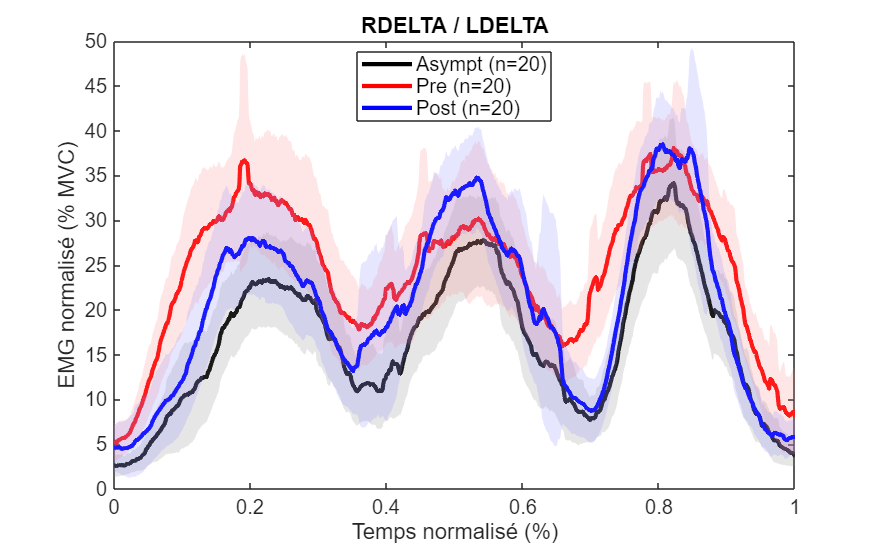

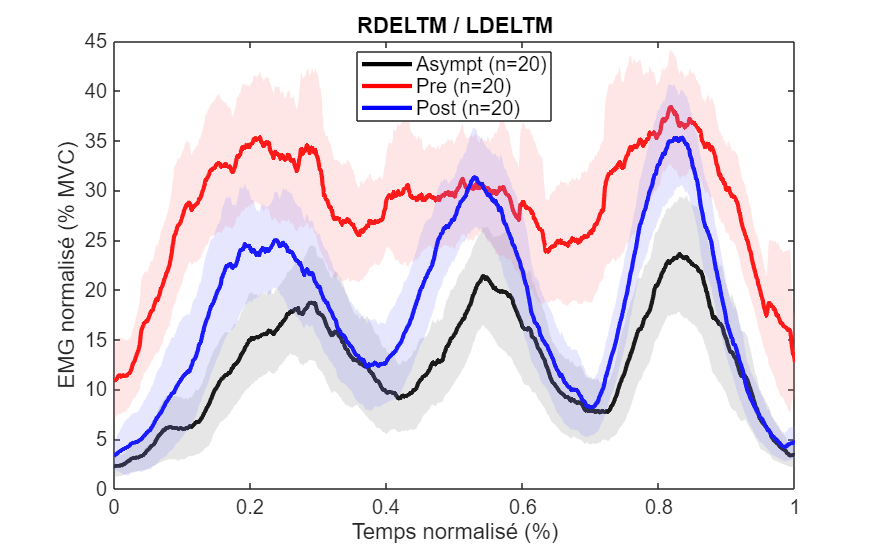

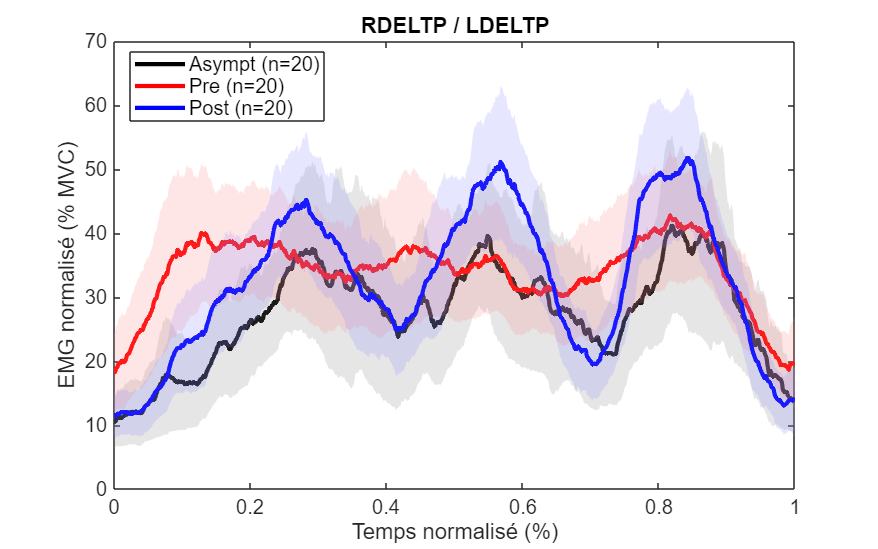

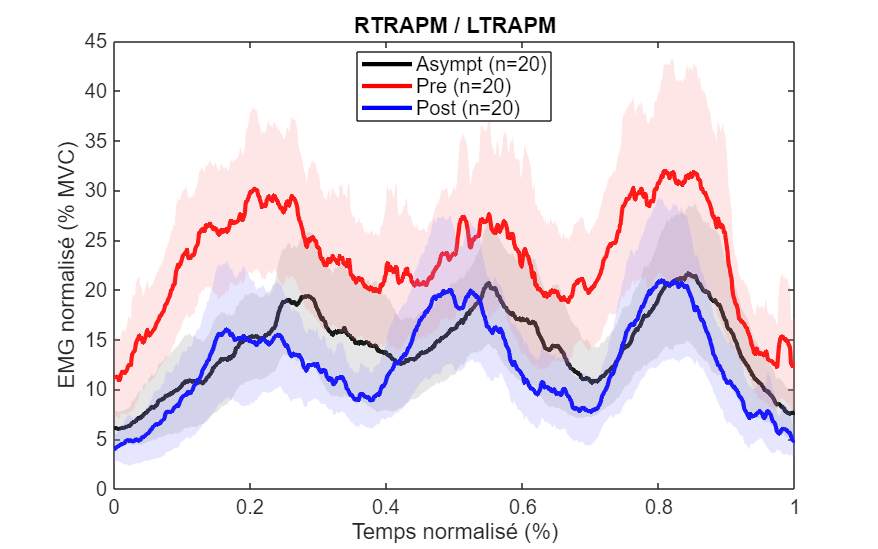

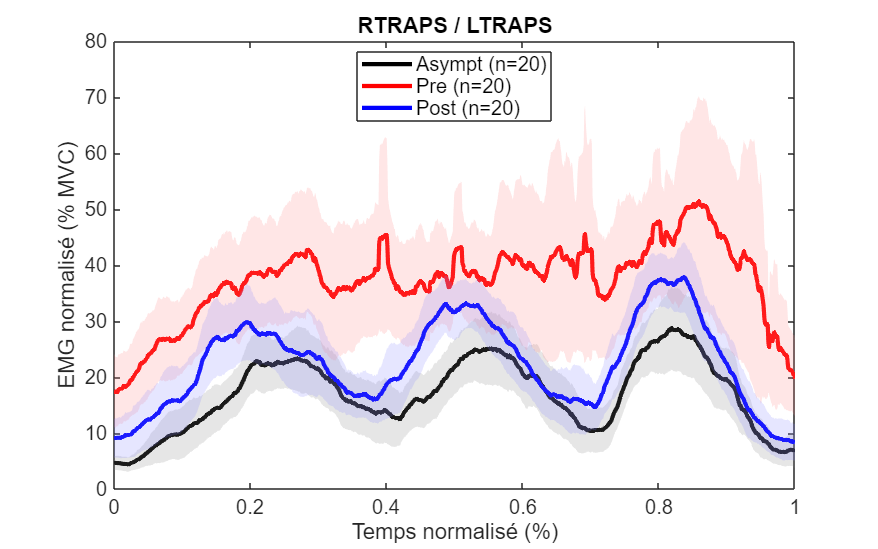

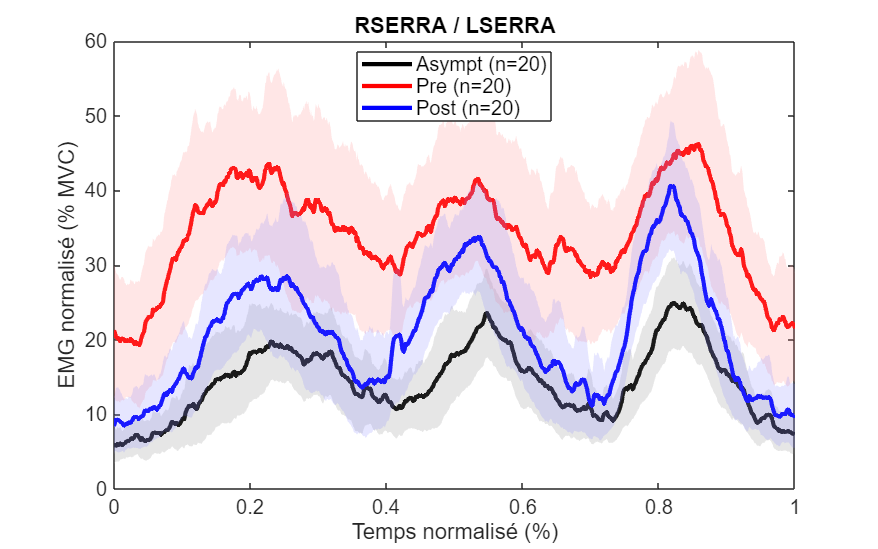


===== Sélection des cycles pour le muscle 1: RDELTA =====
Veuillez sélectionner les points de début et de fin de 3 cycles pour RDELTA - Asympt


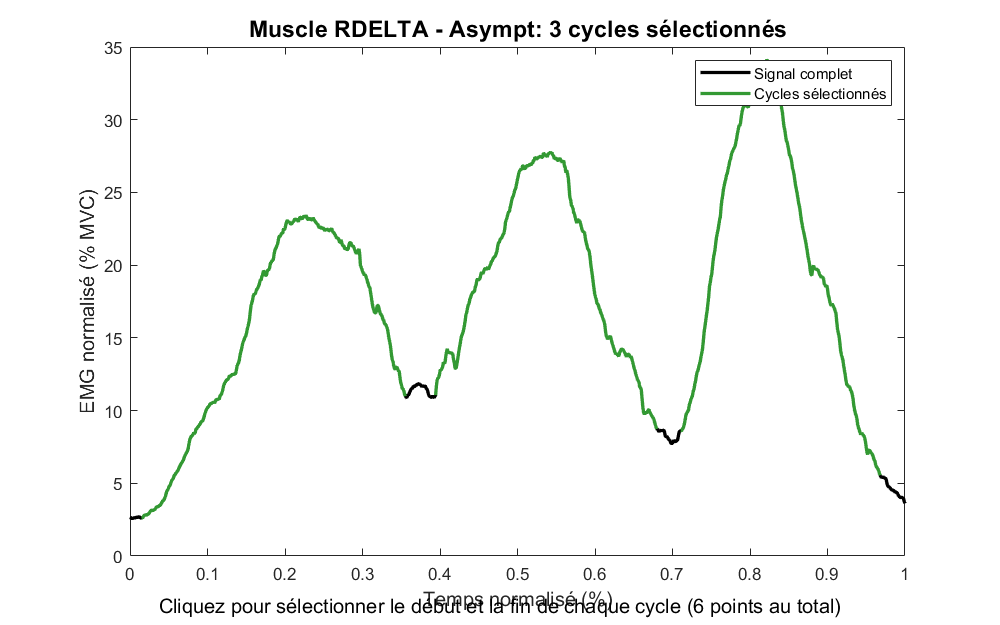

Veuillez sélectionner les points de début et de fin de 3 cycles pour RDELTA - Pre


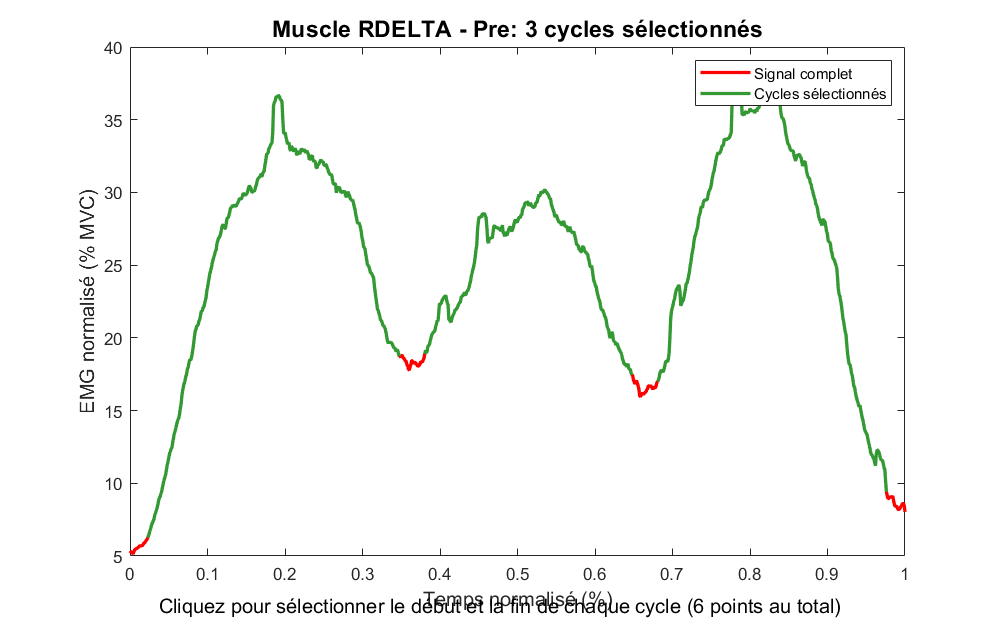

Veuillez sélectionner les points de début et de fin de 3 cycles pour RDELTA - Post

===== Sélection des cycles pour le muscle 2: RDELTM =====


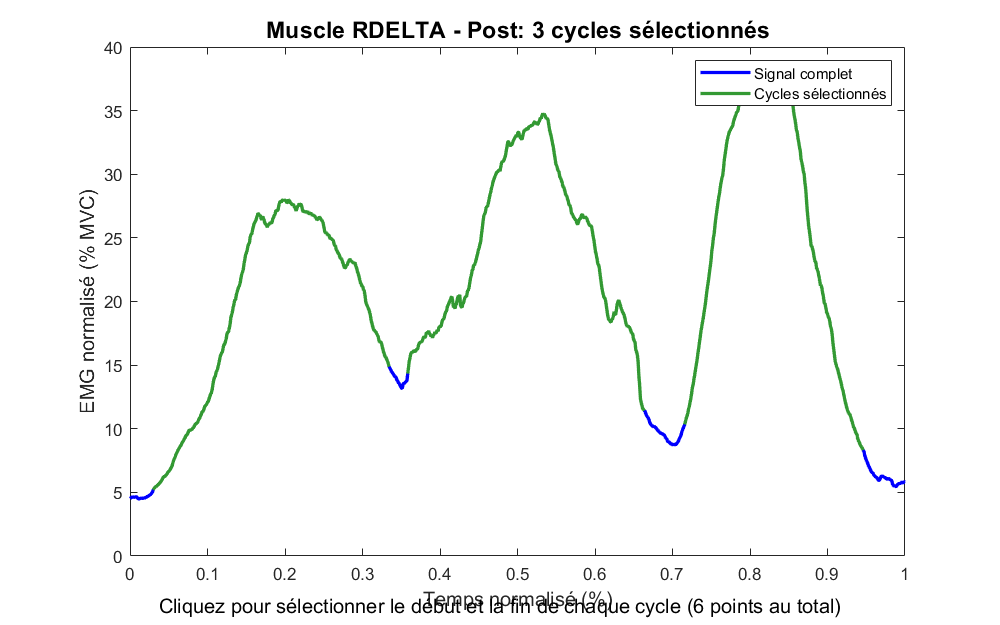

Veuillez sélectionner les points de début et de fin de 3 cycles pour RDELTM - Asympt


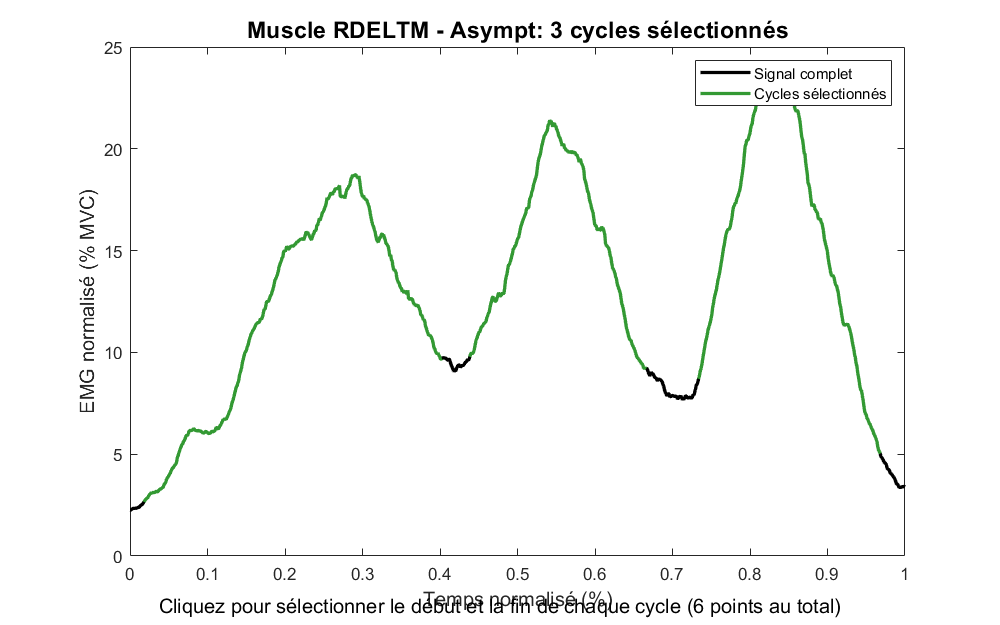

Veuillez sélectionner les points de début et de fin de 3 cycles pour RDELTM - Pre


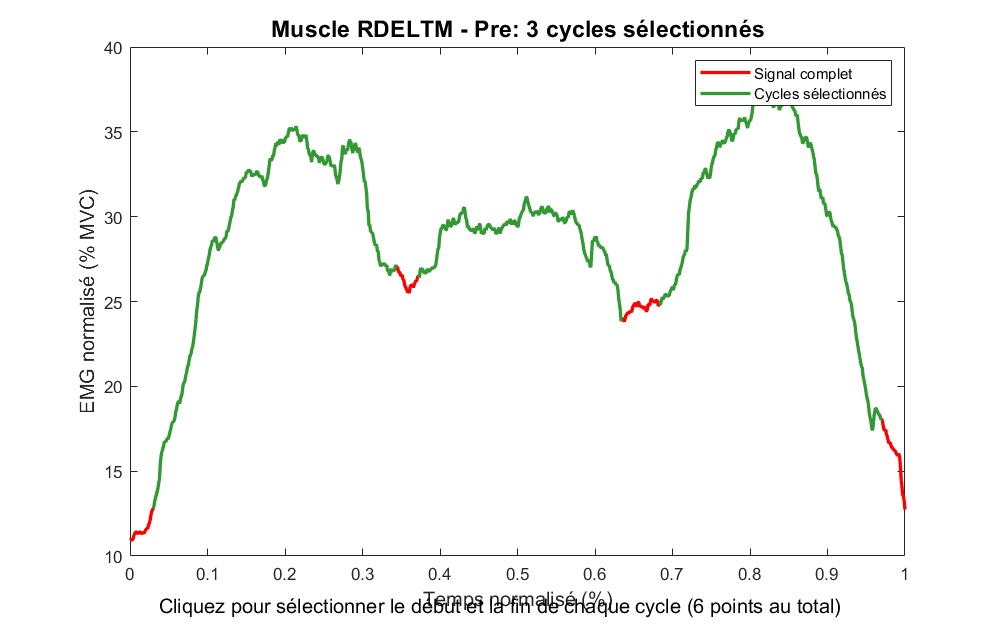

Veuillez sélectionner les points de début et de fin de 3 cycles pour RDELTM - Post

===== Sélection des cycles pour le muscle 3: RDELTP =====


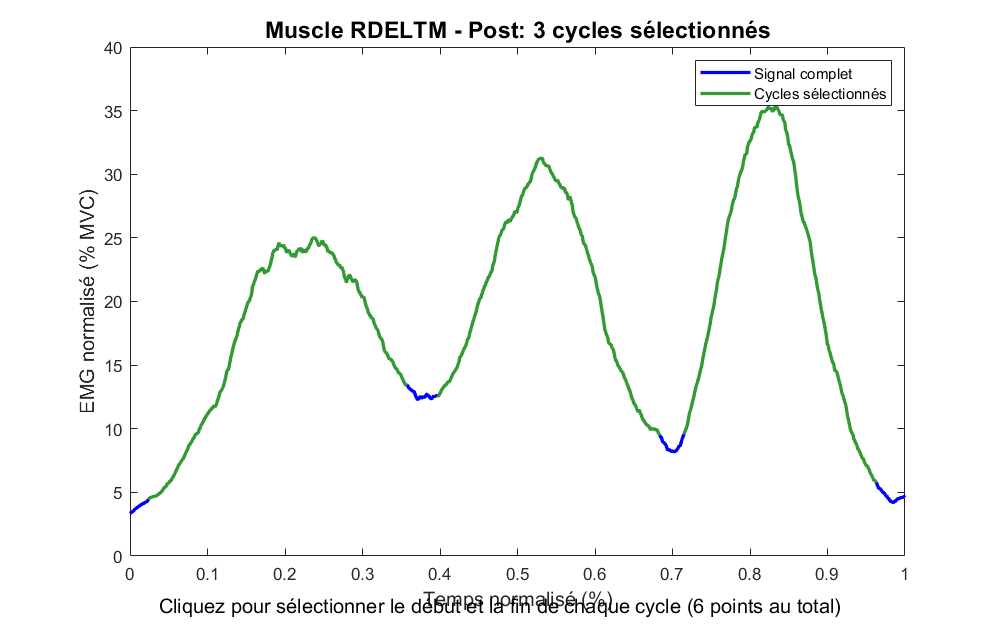

Veuillez sélectionner les points de début et de fin de 3 cycles pour RDELTP - Asympt


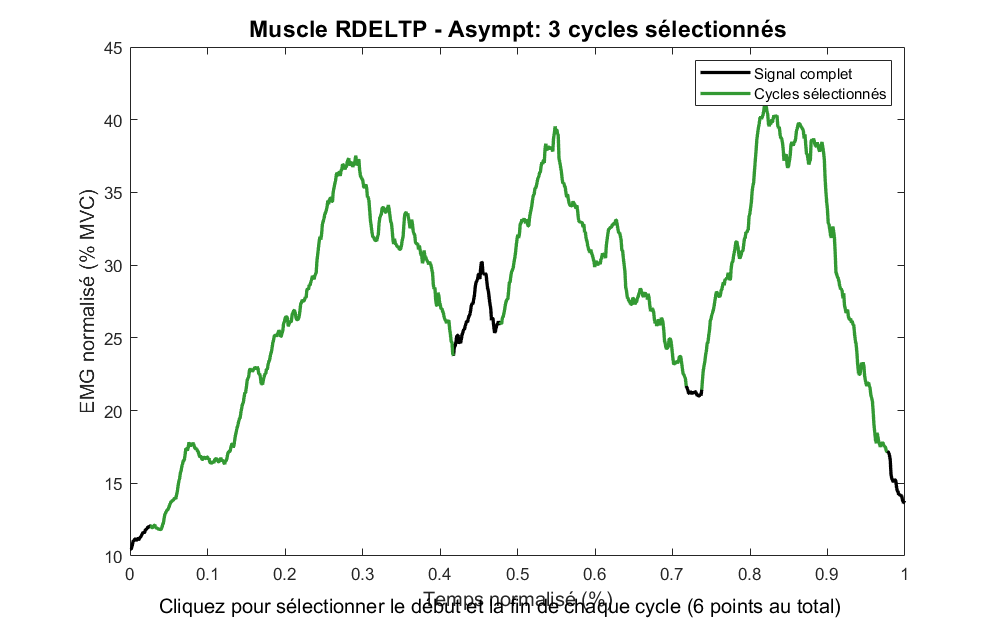

Veuillez sélectionner les points de début et de fin de 3 cycles pour RDELTP - Pre


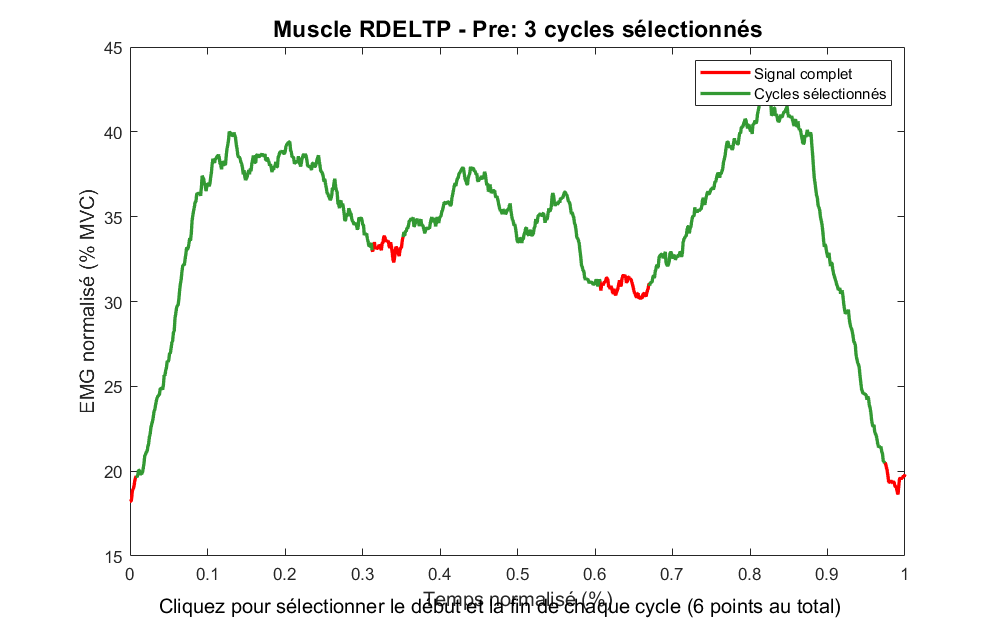

Veuillez sélectionner les points de début et de fin de 3 cycles pour RDELTP - Post

===== Sélection des cycles pour le muscle 4: RTRAPM =====


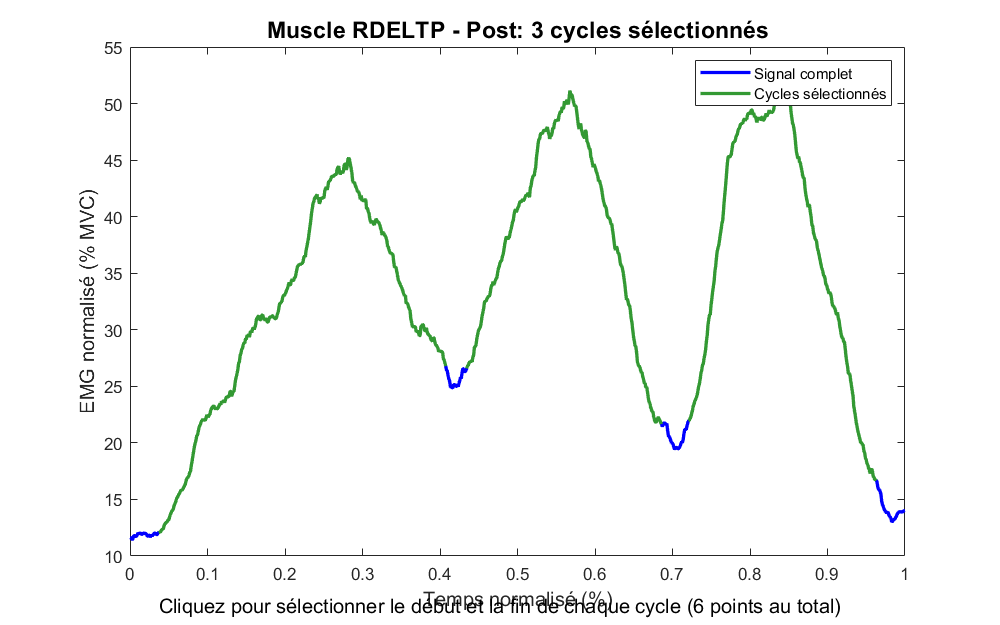

Veuillez sélectionner les points de début et de fin de 3 cycles pour RTRAPM - Asympt


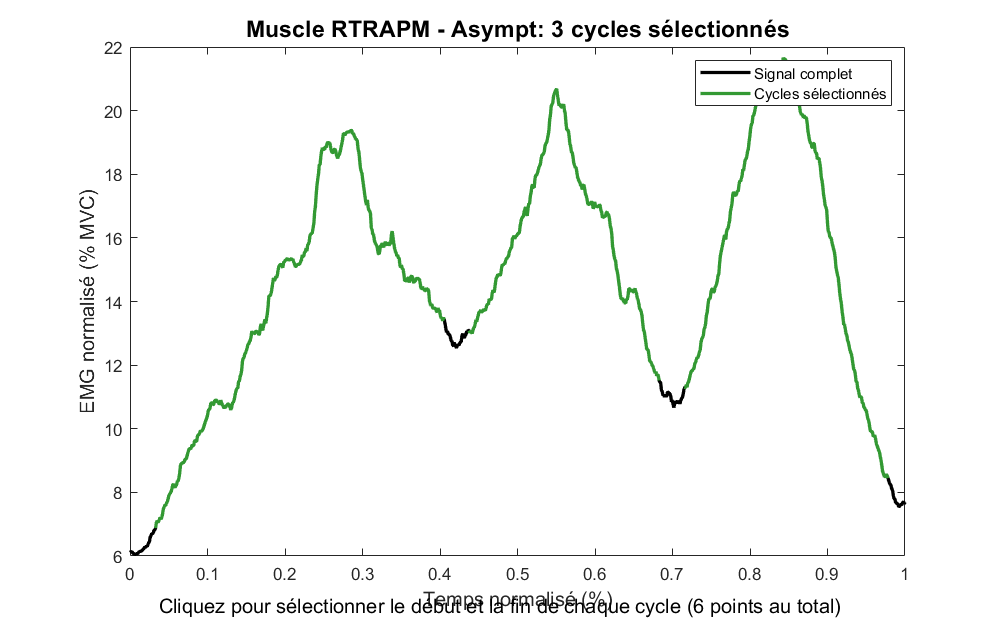

Veuillez sélectionner les points de début et de fin de 3 cycles pour RTRAPM - Pre


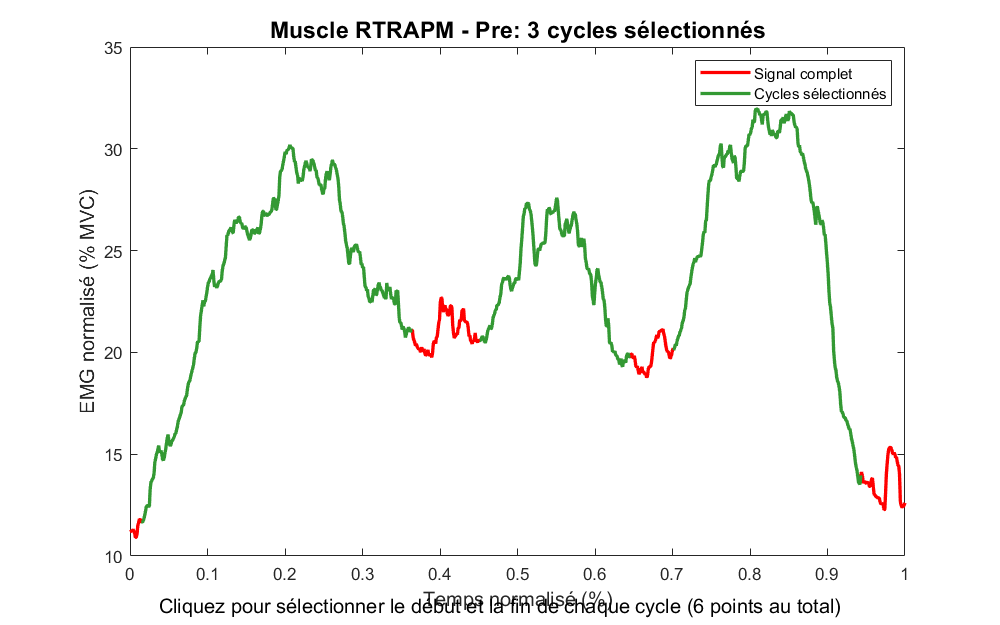

Veuillez sélectionner les points de début et de fin de 3 cycles pour RTRAPM - Post

===== Sélection des cycles pour le muscle 5: RTRAPS =====


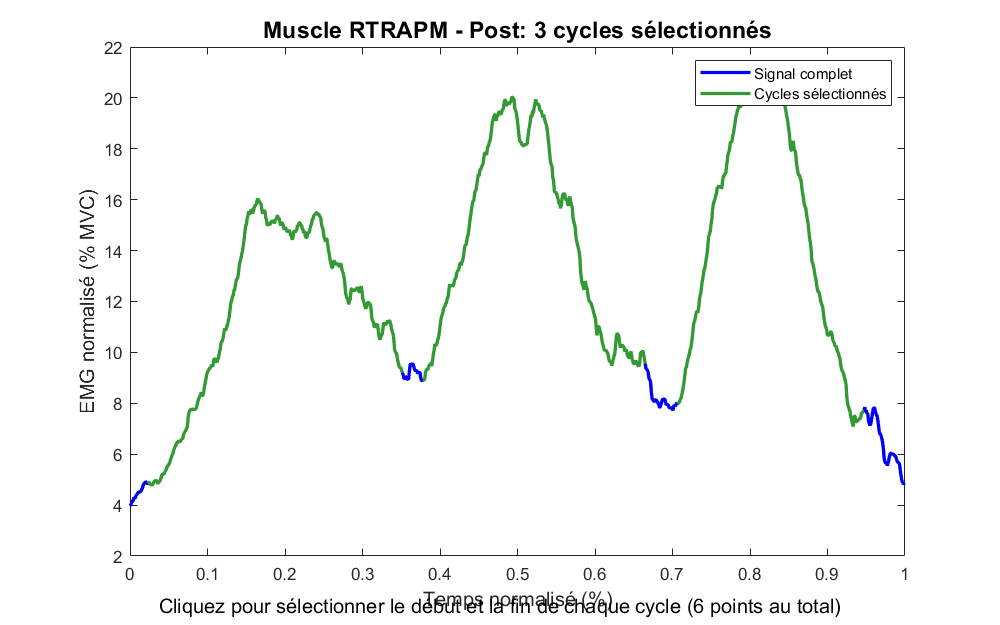

Veuillez sélectionner les points de début et de fin de 3 cycles pour RTRAPS - Asympt


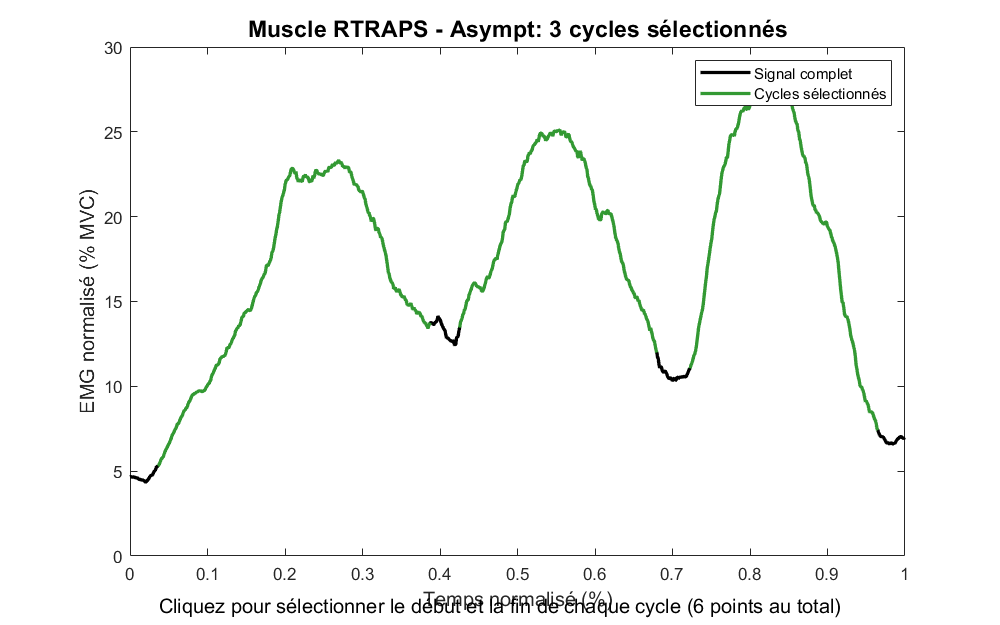

Veuillez sélectionner les points de début et de fin de 3 cycles pour RTRAPS - Pre


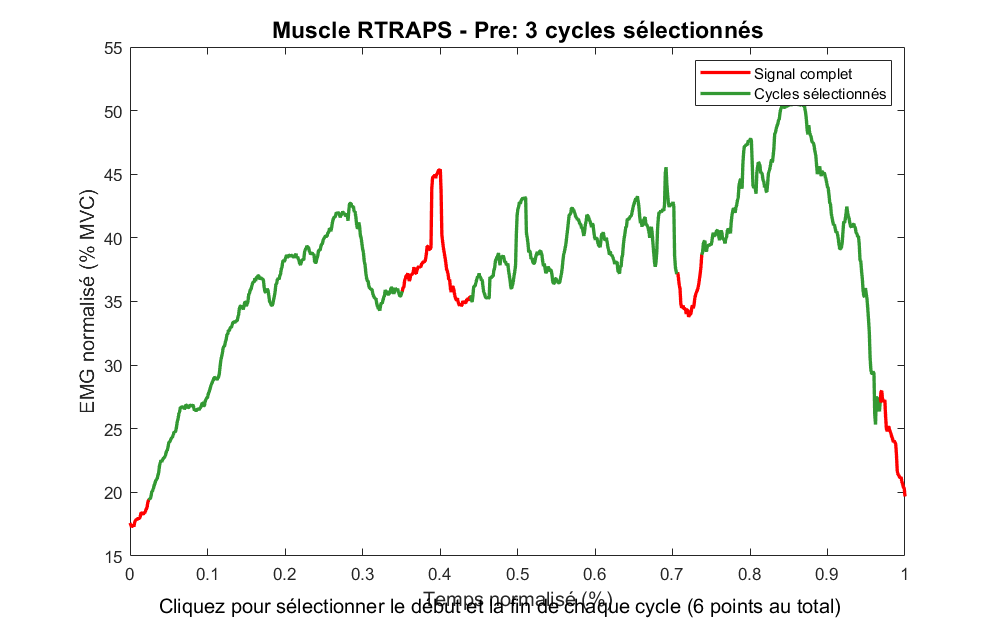

Veuillez sélectionner les points de début et de fin de 3 cycles pour RTRAPS - Post

===== Sélection des cycles pour le muscle 6: RSERRA =====


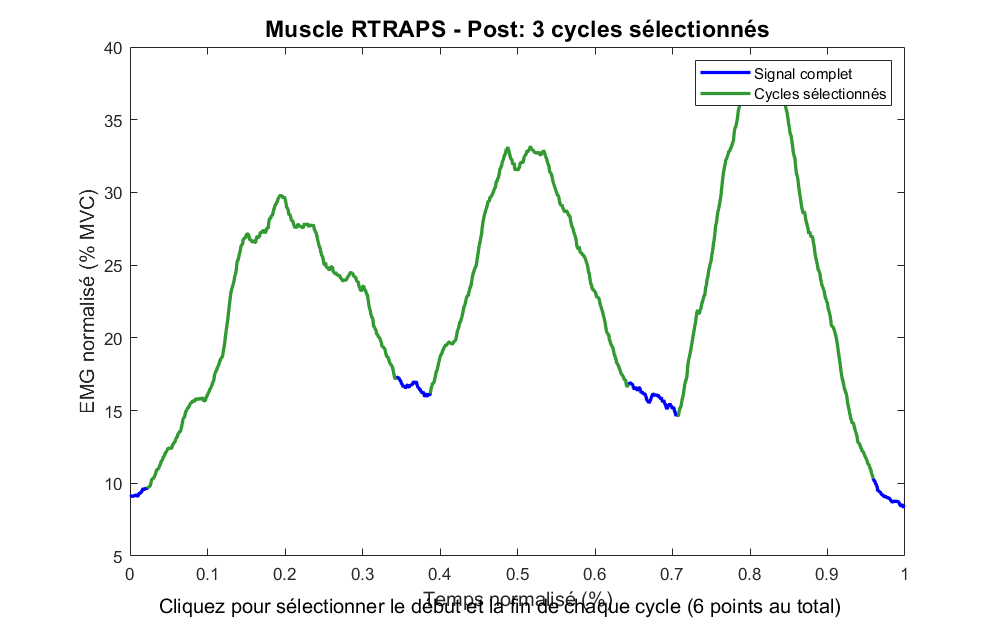

Veuillez sélectionner les points de début et de fin de 3 cycles pour RSERRA - Asympt


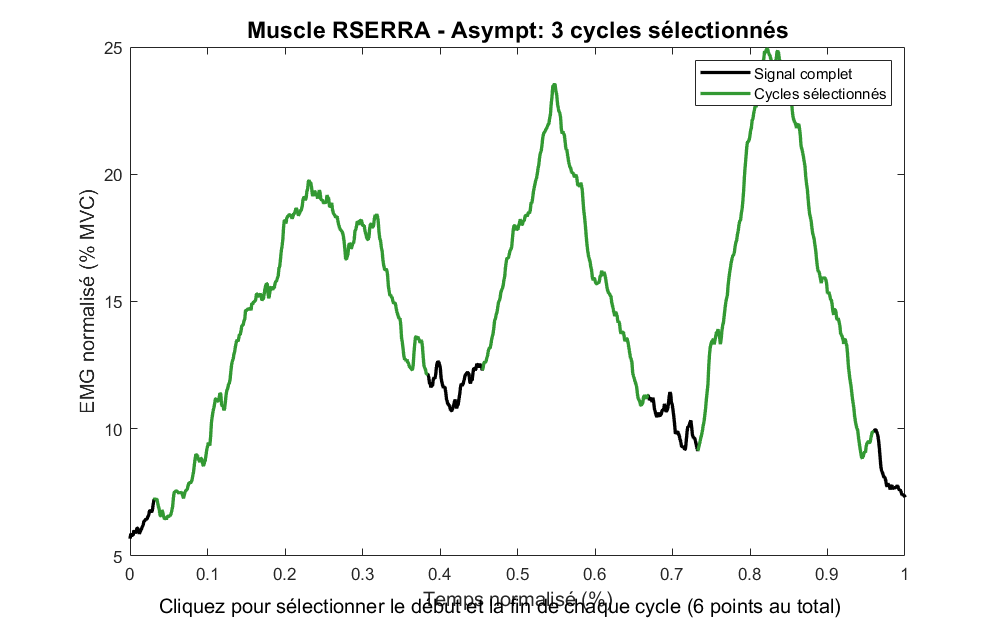

Veuillez sélectionner les points de début et de fin de 3 cycles pour RSERRA - Pre


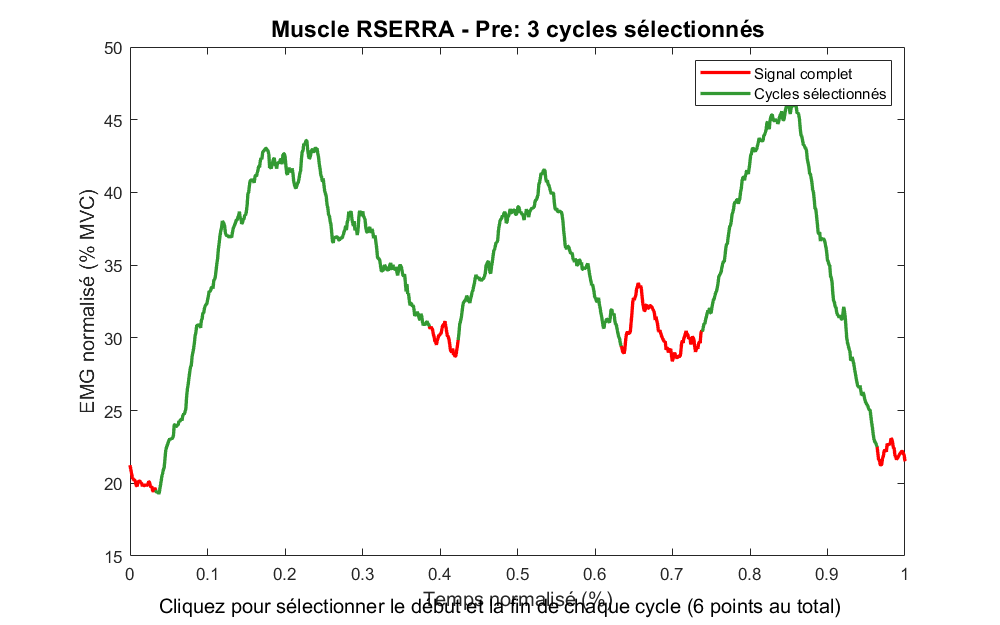

Veuillez sélectionner les points de début et de fin de 3 cycles pour RSERRA - Post


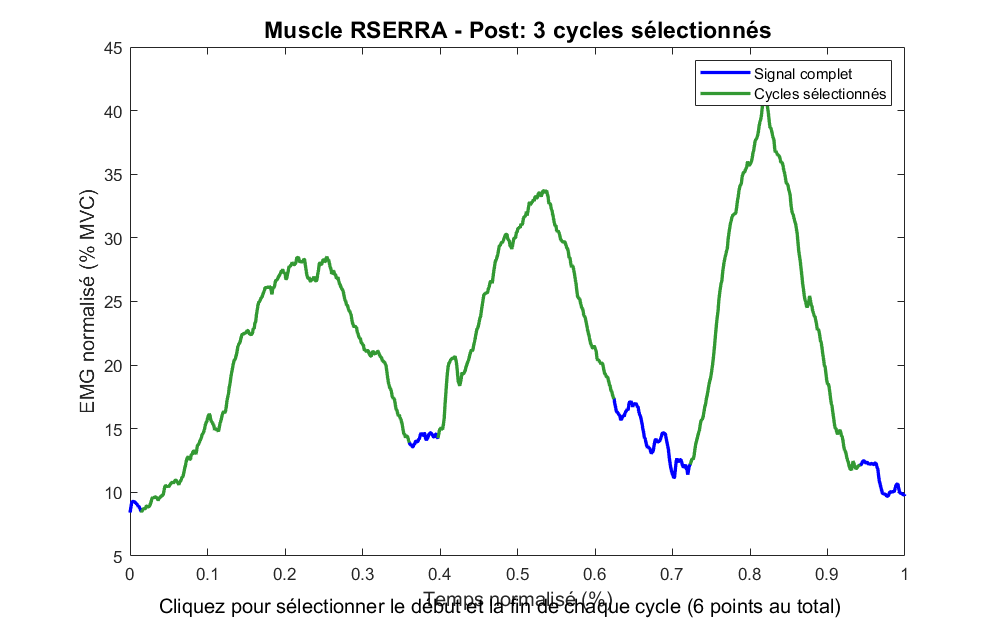


========== RÉSULTATS DES ANALYSES SPM1D ==========
Tableau des p-values et régions significatives:

Muscle          Comparaison          Type Test       Début Cycle (%)      Fin Cycle (%)   p-value        
------------------------------------------------------------------------------------------------------------------------
RDELTA/LDELTA  
                Asympt vs Pre        independent     -1.0                 10.3            0.0102         

========== FIN DES RÉSULTATS SPM1D ==========

Résultats sauvegardés dans: SPM1D_results_20250606_112549.mat

========== RÉSULTATS DES ANALYSES SPM1D ==========
Tableau des p-values et régions significatives:

Muscle          Comparaison          Type Test       Début Cycle (%)      Fin Cycle (%)   p-value        
------------------------------------------------------------------------------------------------------------------------
RDELTA/LDELTA  
                Asympt vs Pre        independent     -1.0                 10.3            0.0102

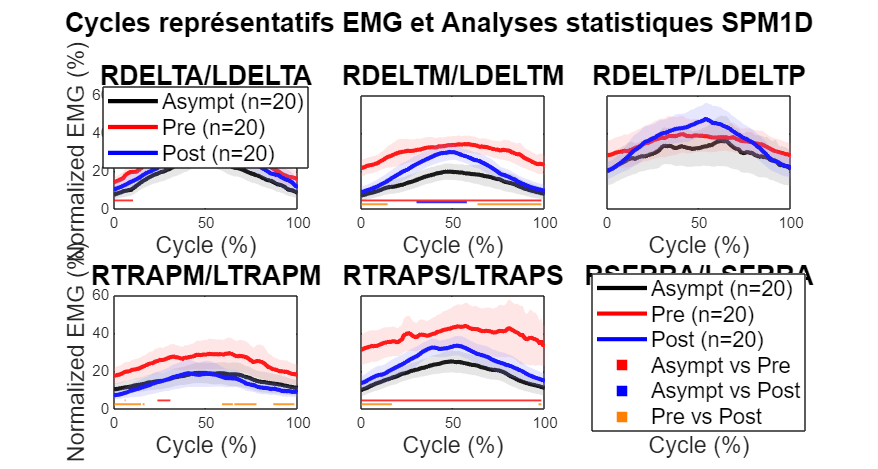


% Exécuter la fonction SPM1D sur les cycles représentatifs moyens
plotCombinedEMGPerSubjectWithSPM1DCycles(data_files);